# Electric Breakdown Phenomena

## Standard Sphere Gaps

### `Relatice air density`


$$\delta = (\frac{b}{1013}) (\frac{273+20}{273+t})$$


b = 1013;
t = 30;

delta = (b/1013)*((273+20))/(273+t)

delta = 0.9670

### Standard Sphere Gaps


$$V={\textrm{kV}}_n$$


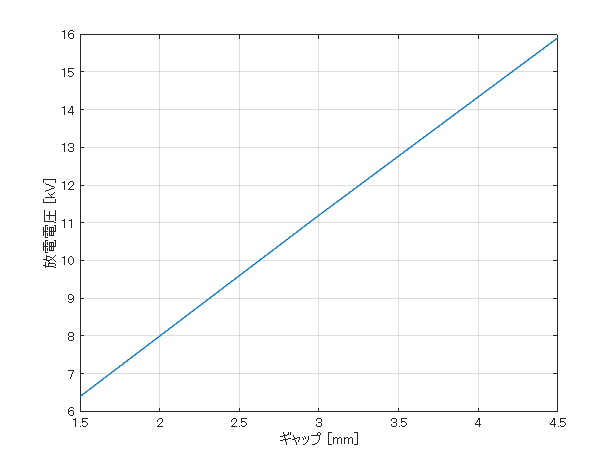

if 0.95<=delta<=1.05
    k =1.0;
else
    disp("値確認");
    quit()
end
    
V_n =[6.4,11.2,15.9]; 
V= k*V_n;

clf;
plot([1.5,3.0,4.5],V);
xlabel('ギャップ [mm]');
ylabel('放電電圧 [kV]');

grid on
box on

## Theorical wave of void dischage 


$$V = \sqrt{2} V_{in} sin(\omega t)
$$



$$V_a = 0.8V=0.8\sqrt{2}Vsin(\omega t)
$$


omega = 2*pi*60;
t= (0:0.01:20)*1e-3;


$$V_g =0.8 \sqrt{2} V_i$$


Vg: ボイド放電開始電圧 , Vi: ボイド放電開始電圧（測定値）

Vg=9.9; %kV


V_in=1.2*Vg;% 120%

V = sqrt(2)*V_in*sin(omega*t);

Va=0.8*V;

$V_a^{\prime}$:ボイド放電の理想波形

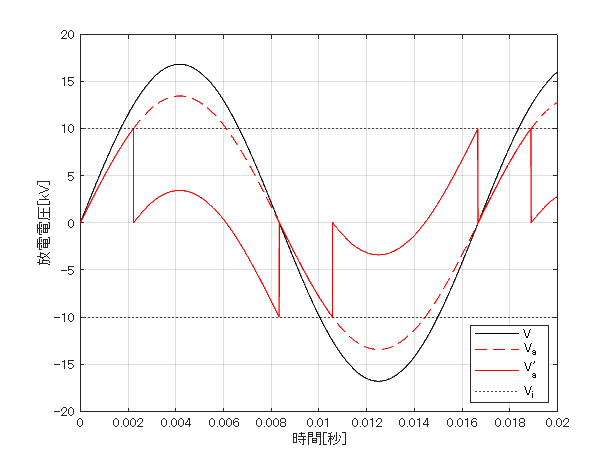

Vat=zeros(1,length(t));
Vat(1)=Va(1);
diffVa=diff(Va);
for iT=2:length(t)
    Vat(iT)=Vat(iT-1)+diffVa(iT-1);

    if abs(Vat(iT))>abs(Vi)
        Vat(iT)=0; 
    end
end

clf;
p=plot(t,V,'-k');

hold on

pa=plot(t,Va,'--r');

pat=plot(t,Vat,'-r');

vi=yline([Vi,-Vi],':k');
legend([p,pa,pat,vi(1)],{'V','V_a','V_a^{\prime}','V_i'},'Location','best');

xlabel('時間[秒]');
ylabel('放電電圧[kV]');

grid on
box on

## `V-t Characteristics`

## 
$$n = \frac{\log{t_1}-\log{t_2}}{\log{V_2}-\log{V_1}}$$


t_1=180;
t_2=10;
V_1=20; %1次電圧
V_2=24; %1次電圧

n=( log(t_1) - log(t_2) ) /(log(V_2) - log(V_1))

n = 15.8532


$$V^n t =const$$


const_1 = V_1^n *t_1

const_1 = 7.5980e+22

const_2 = V_2^n *t_2

const_2 = 7.5980e+22

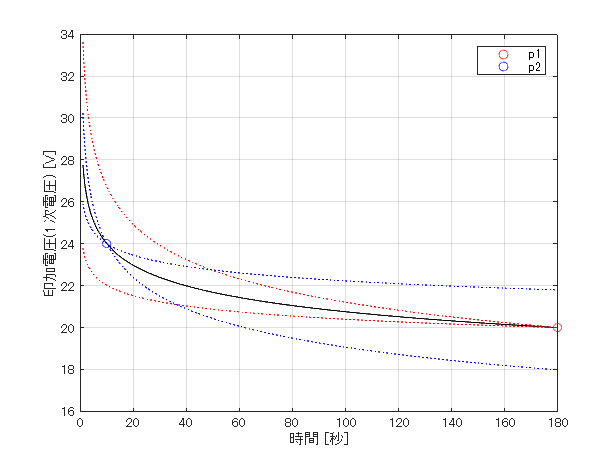

const = const_1;

t=1:0.1:180;
V= (const./t).^(1/n);

clf;
plot(t,V,"-k");

hold on

p1=scatter(t_1,V_1,30,[1,0,0]);
p2=scatter(t_2,V_2,30,[0,0,1]);

n_lb=10;
n_ub=30;
V_lb_t1= (V_1^n_lb*t_1./t).^(1/n_lb);
V_ub_t1= (V_1^n_ub*t_1./t).^(1/n_ub);

p_lb_t1=plot(t,V_lb_t1,":r");
p_ub_t1=plot(t,V_ub_t1,":r");

V_lb_t2= (V_2^n_lb*t_2./t).^(1/n_lb);
V_ub_t2= (V_2^n_ub*t_2./t).^(1/n_ub);

p_lb_t2=plot(t*1e3,V_lb_t2,":b");
p_ub_t2=plot(t*1e3,V_ub_t2,":b");

xlabel('時間 [ms]');
ylabel('印加電圧(1次電圧) [V]');

legend([p1,p2],{'p1','p2'},'Location','northeast');

grid on
box on